## Del 3 Färg

### 1) Spectral power distribution

load spectra.mat;
who


Your variables are:

B            R            Xm           Yp           b1           g6           
C            R1           Xober        Z            b2           map          
C1           R2           Xp           Z1           b3           plank90K     
C2           Tungsten60W  Y            Z2           b4           r1           
CIED50       X            Y1           Z3           b5           r2           
CIED65       X1           Y2           Z4           b6           r3           
CM           X2           Y3           Zber         chips20      r4           
G            X3           Y4           Zc           f11          r5           
K            X4           Yber         Zcm          g1           r6           
K1           XYZ          Yc           Zm           g2           wavelength   
M            Xber         Ycm          Zober        g3           xyz          
M1           Xc           Ym           Zp           g4           
P            Xcm          Yober        ans 


figure;
plot(wavelength, xyz)

**1.1**

[X,Y,Z] = spectra2xyz(1,CIED65);

**1.2**

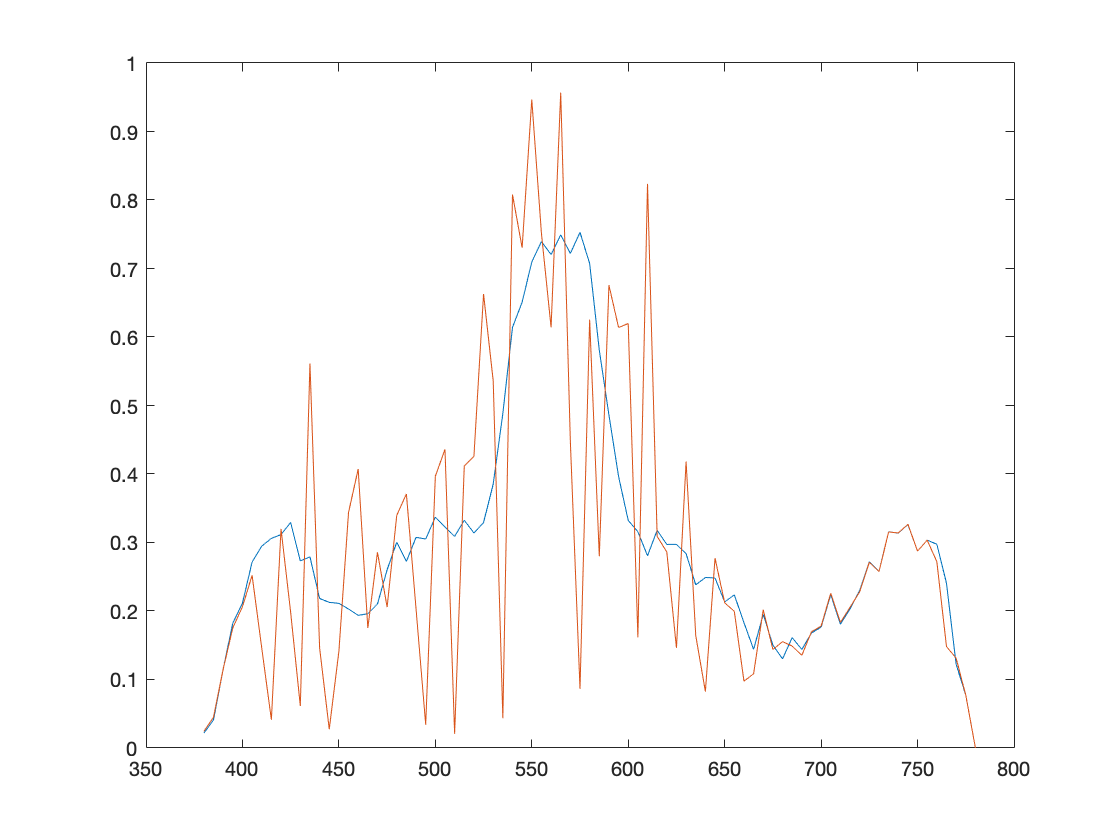

figure;
plot(wavelength, R1);
hold on
plot(wavelength, R2);


[X1,Y1,Z1] = spectra2xyz(R1,CIED65);
[X2,Y2,Z2] = spectra2xyz(R2,CIED65);

**1.3-1.4**

[X3,Y3,Z3] = spectra2xyz(R1,f11);
[X4,Y4,Z4] = spectra2xyz(R2,f11);

**1.5**

[r1,g1,b1] = myxyz2rgb(X1,Y1,Z1)

r1 = 0.4005

g1 = 0.5560

b1 = 0.2022

[r2,g2,b2] = myxyz2rgb(X2,Y2,Z2)

r2 = 0.4005

g2 = 0.5560

b2 = 0.2022

[r3,g3,b3] = myxyz2rgb(X3,Y3,Z3)

r3 = 0.4483

g3 = 0.6040

b3 = 0.0870

[r4,g4,b4] = myxyz2rgb(X4,Y4,Z4)

r4 = 0.6704

g4 = 0.6760

b4 = 0.1196

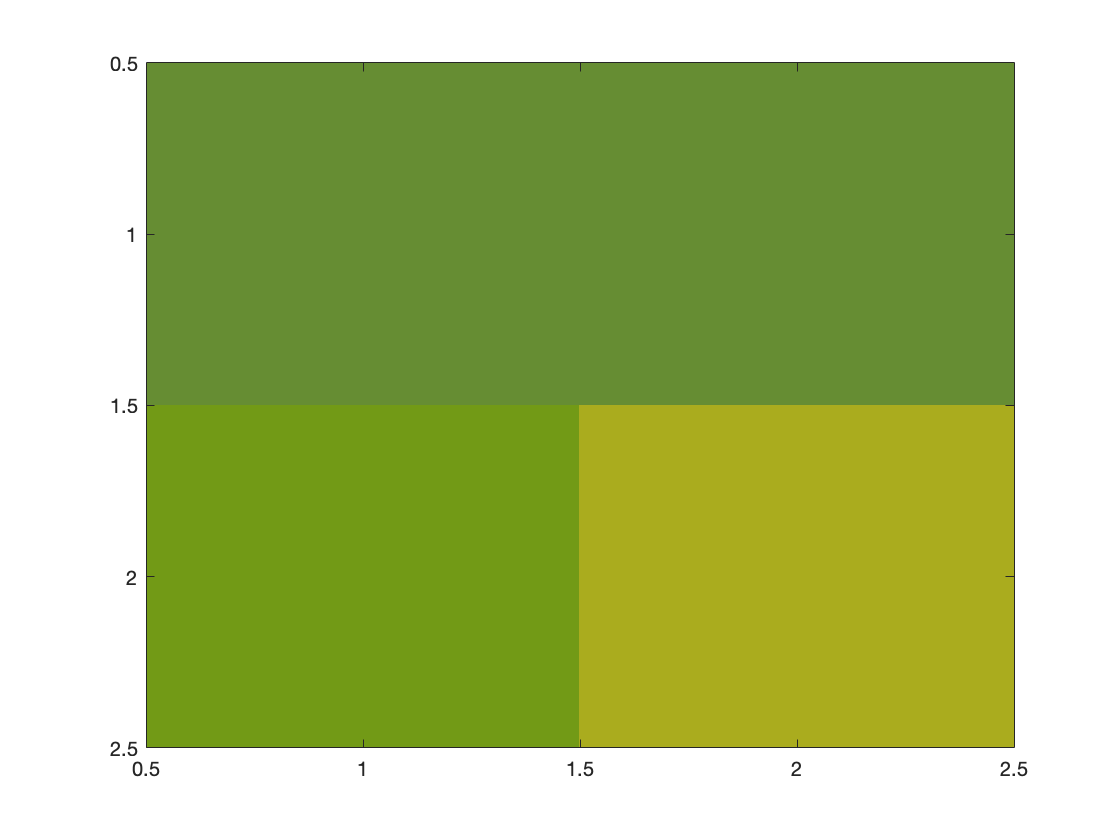


map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4];
map=min(1,max(0,map));

figure;
image([1 2; 3 4]);
colormap(map)

### 2) Dot-on-Dot and Dot-off-Dot Halftoning

**2.1**

C = 0.5;
M = 0.5;
P = 0.5;
CM = 0.5;

Xp = 80.43;
Yp = 84.00;
Zp = 96.50;

Xc = 25.84;
Yc = 42.52;
Zc = 80.88;

Xm = 37.36;
Ym = 18.44;
Zm = 27.52;

Xcm = 7.40;
Ycm = 5.74;
Zcm = 40.36;

Xober = C*Xc + M*Xm

Xober = 31.6000

Yober = C*Yc + M*Ym

Yober = 30.4800

Zober = C*Zc + M*Zm

Zober = 54.2000


Xber = P*Xp + CM*Xcm

Xber = 43.9150

Yber = P*Yp + CM*Ycm

Yber = 44.8700

Zber = P*Zp + CM*Zcm

Zber = 68.4300

**2.2**

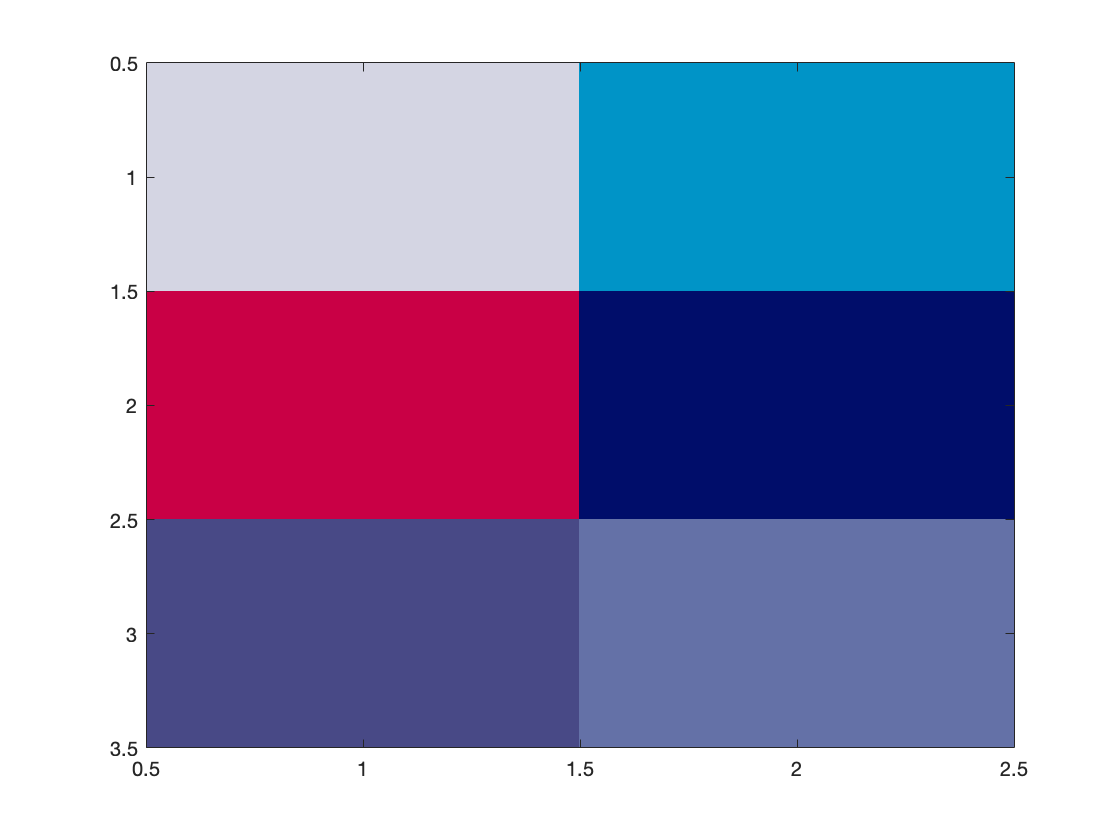

[r1,g1,b1] = myxyz2rgb(Xp,Yp,Zp);
[r2,g2,b2] = myxyz2rgb(Xc,Yc,Zc);
[r3,g3,b3] = myxyz2rgb(Xm,Ym,Zm);
[r4,g4,b4] = myxyz2rgb(Xcm,Ycm,Zcm);
[r5,g5,b5] = myxyz2rgb(Xober,Yober,Zober);
[r6,g6,b6] = myxyz2rgb(Xber,Yber,Zber);

map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4; r5 g5 b5; r6 g6 b6];
map=min(1,max(0,map));

figure;
image([1 2; 3 4; 5 6]);
colormap(map)

### 3) Color Halftoning According to Demichel

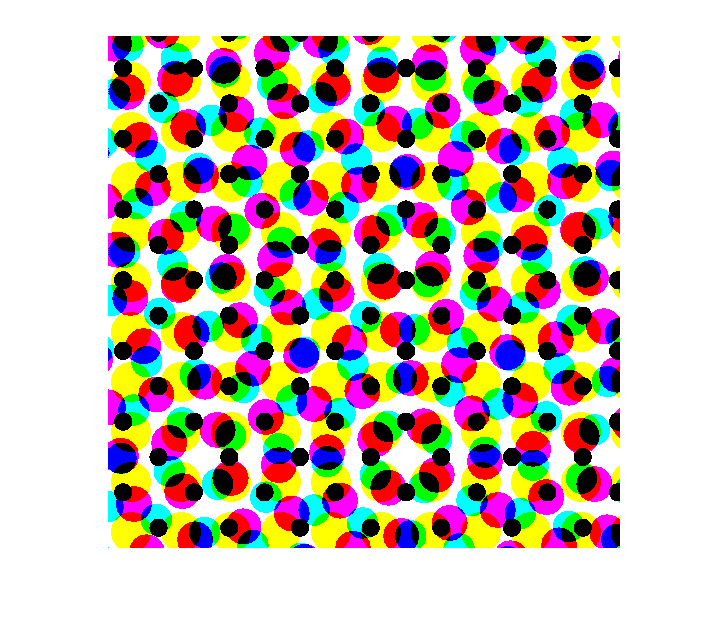

[C, M, Y, K]=tiffread('halftone');

[R, G, B]=cmyk2rgb(C, M, Y, K);
imshowrgb(R, G, B);

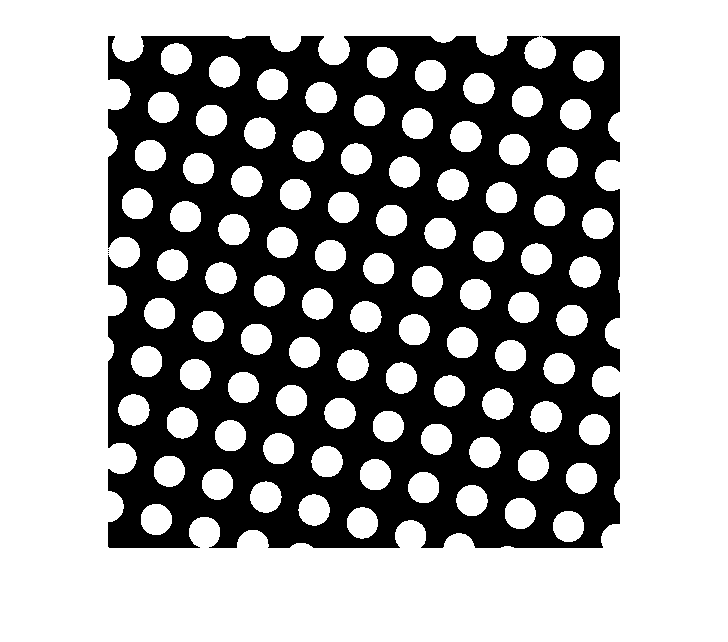


imshow(C)

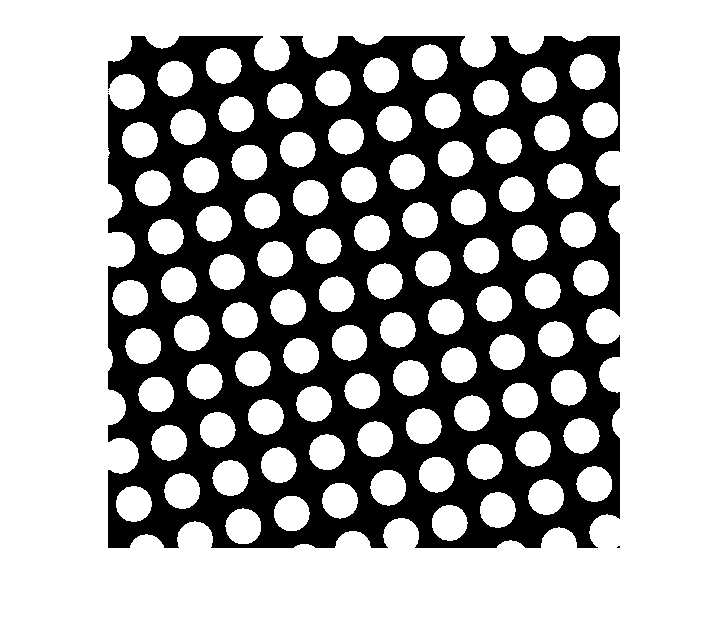

imshow(M)

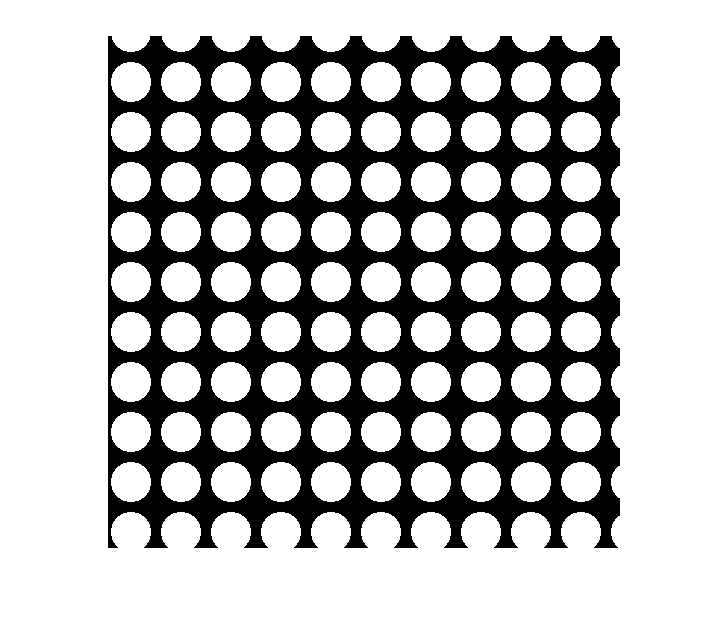

imshow(Y)

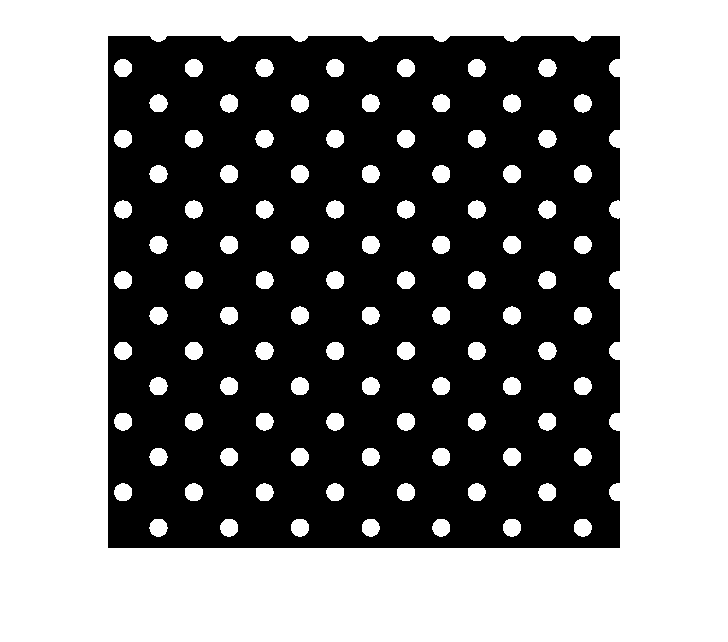

imshow(K)

**3.1**

C1=C(129:384,129:384);
M1=M(129:384,129:384);
Y1=Y(129:384,129:384);
K1=K(129:384,129:384);

Demichel_test(C1,M1,Y1,K1);

C2=C(139:394,129:384);

Demichel_test(C2, M1, Y1, K1);

### 4) Color Adjustment in CIELAB

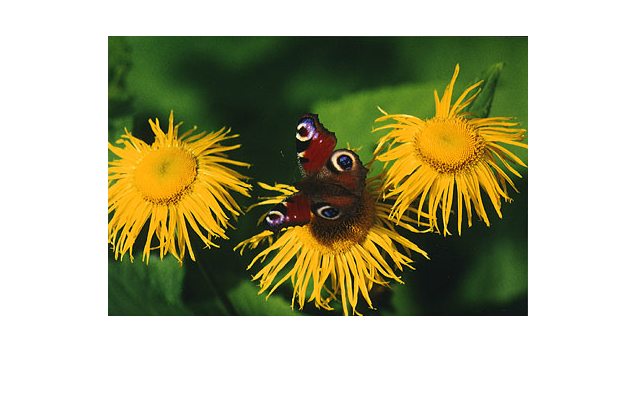

[R, G, B]=tiffread('Butterfly'); 
imshowrgb(R ,G, B);

**4.1**

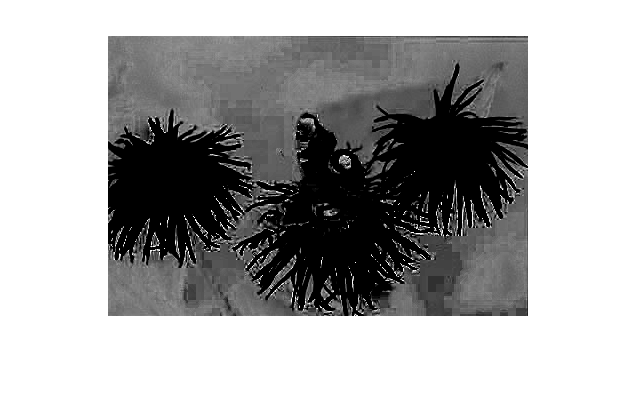

[C, M, Y, K]=rgb2cmyk(R,G,B);

imshow(C)

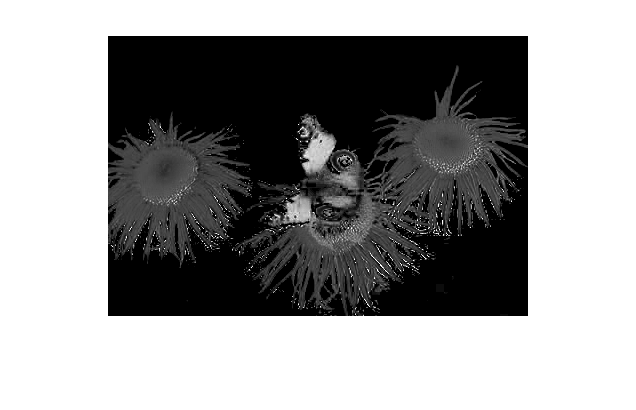


imshow(M) 

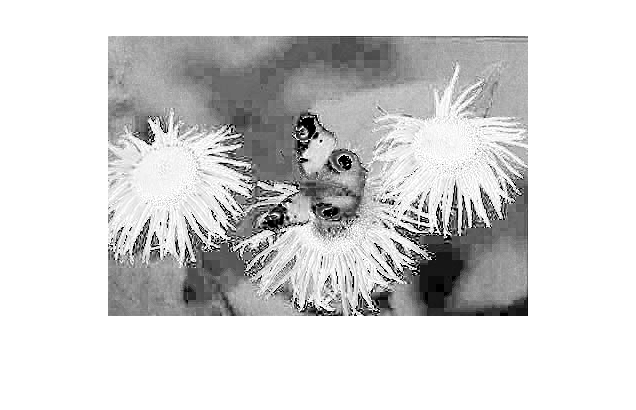


imshow(Y) 

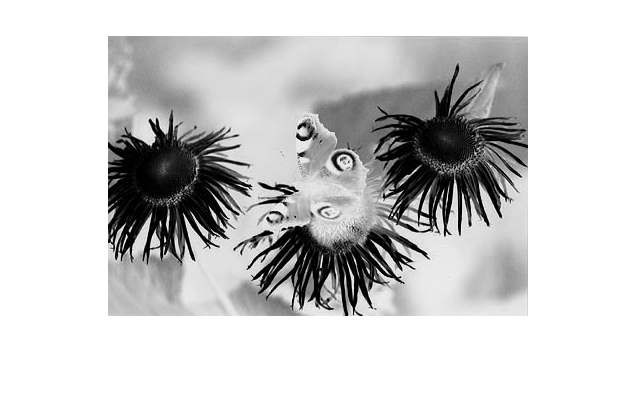


imshow(K)

**4.2**

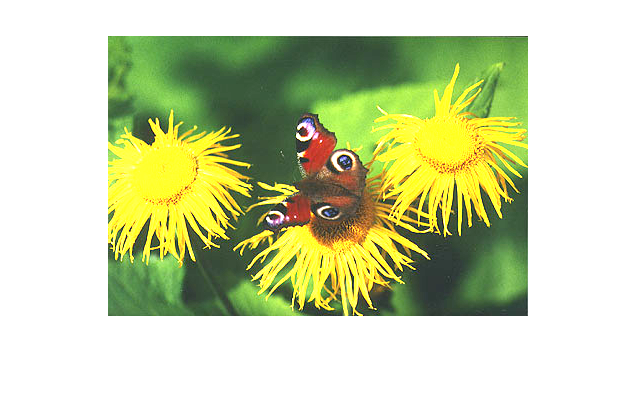

[L, a, b]=myrgb2lab(R,G,B);

[R2, G2, B2]=mylab2rgb(L+20, a, b);
imshowrgb(R2, G2, B2)

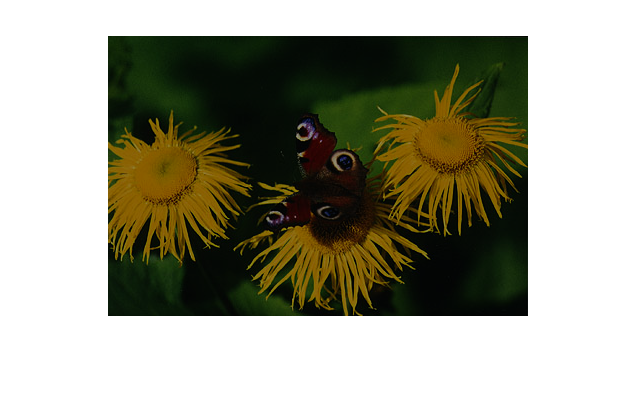


[R3, G3, B3]=mylab2rgb(L-20, a, b);
imshowrgb(R3, G3, B3)

**4.3**

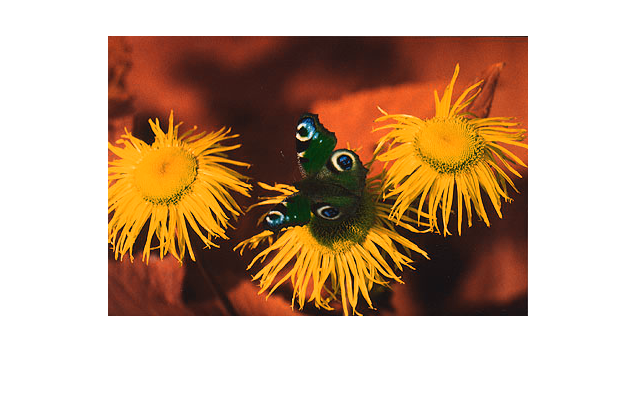

[R2, G2, B2]=mylab2rgb(L, -a, b);
imshowrgb(R2, G2, B2)

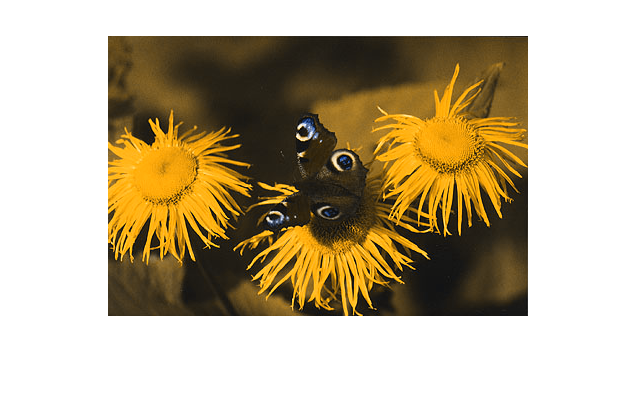


[R3, G3, B3]=mylab2rgb(L, 0, b);
imshowrgb(R3, G3, B3)

**4.4**

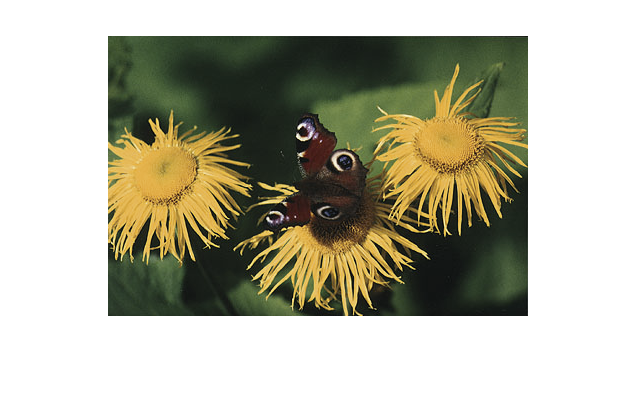

[R2, G2, B2]=mylab2rgb(L, 0.5*a, 0.5*b);
imshowrgb(R2, G2, B2)

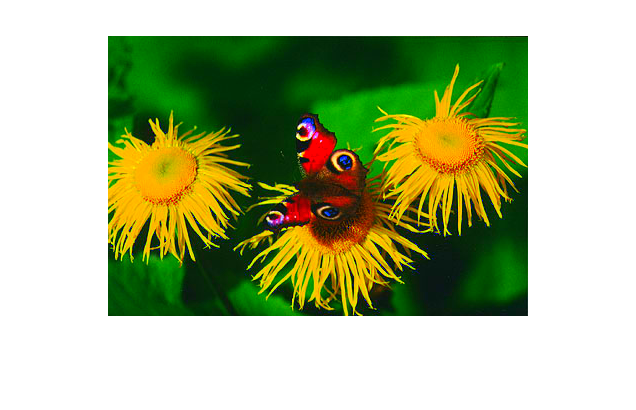


[R3, G3, B3]=mylab2rgb(L, 3*a, 3*b);
imshowrgb(R3, G3, B3)

### 5) Light sources, CIEXYZ and CIELAB

**5.1**

[X1,Y1,Z1] = spectra2xyz(1,CIED65)

X1 = 95.0437

Y1 = 100

Z1 = 108.8818

[X2,Y2,Z2] = spectra2xyz(1,Tungsten60W)

X2 = 112.9853

Y2 = 100

Z2 = 28.5810

[X3,Y3,Z3] = spectra2xyz(1,plank90K)

X3 = 97.0578

Y3 = 100

Z3 = 141.1759

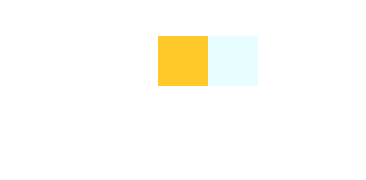


[R1, G1, B1] = myxyz2rgb(X1, Y1, Z1);
[R2, G2, B2] = myxyz2rgb(X2, Y2, Z2);
[R3, G3, B3] = myxyz2rgb(X3, Y3, Z3);

RGB = [R1 G1 B1; R2 G2 B2; R3 G3 B3];

showRGB(RGB)

**5.2**

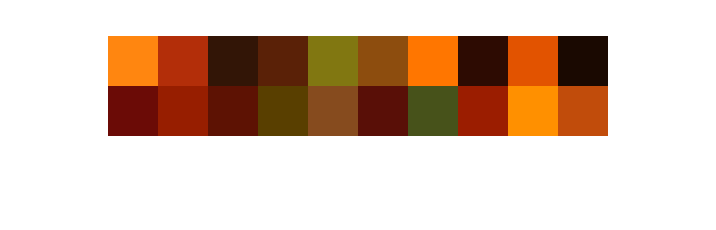

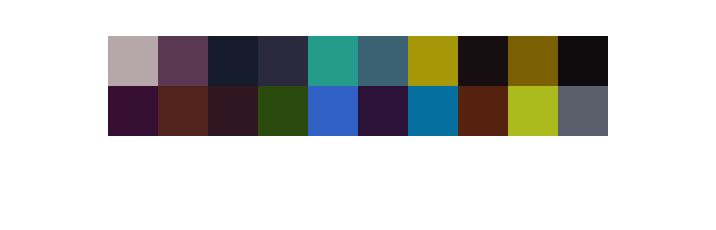

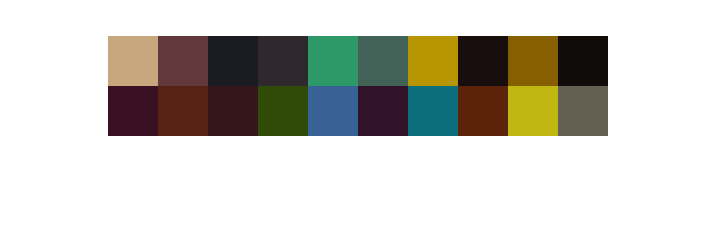

showRGB_20

**5.3**

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


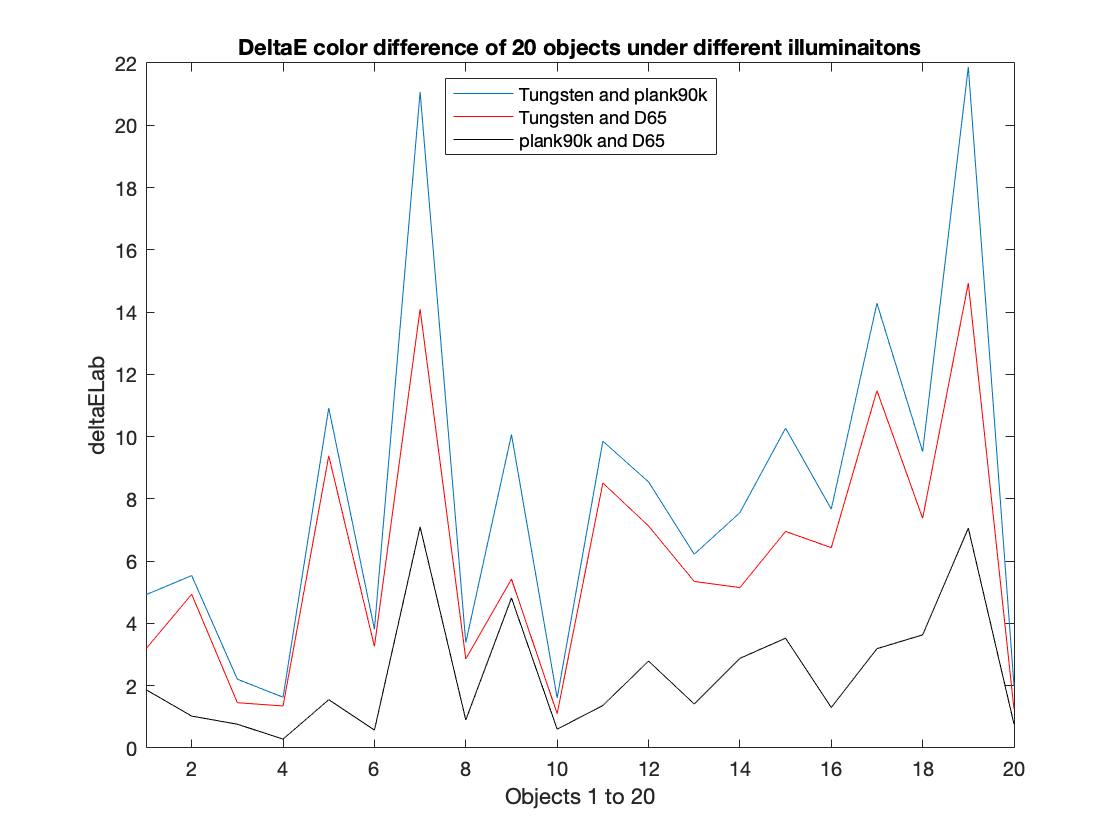

plot_deltaE

**5.4-5.5**

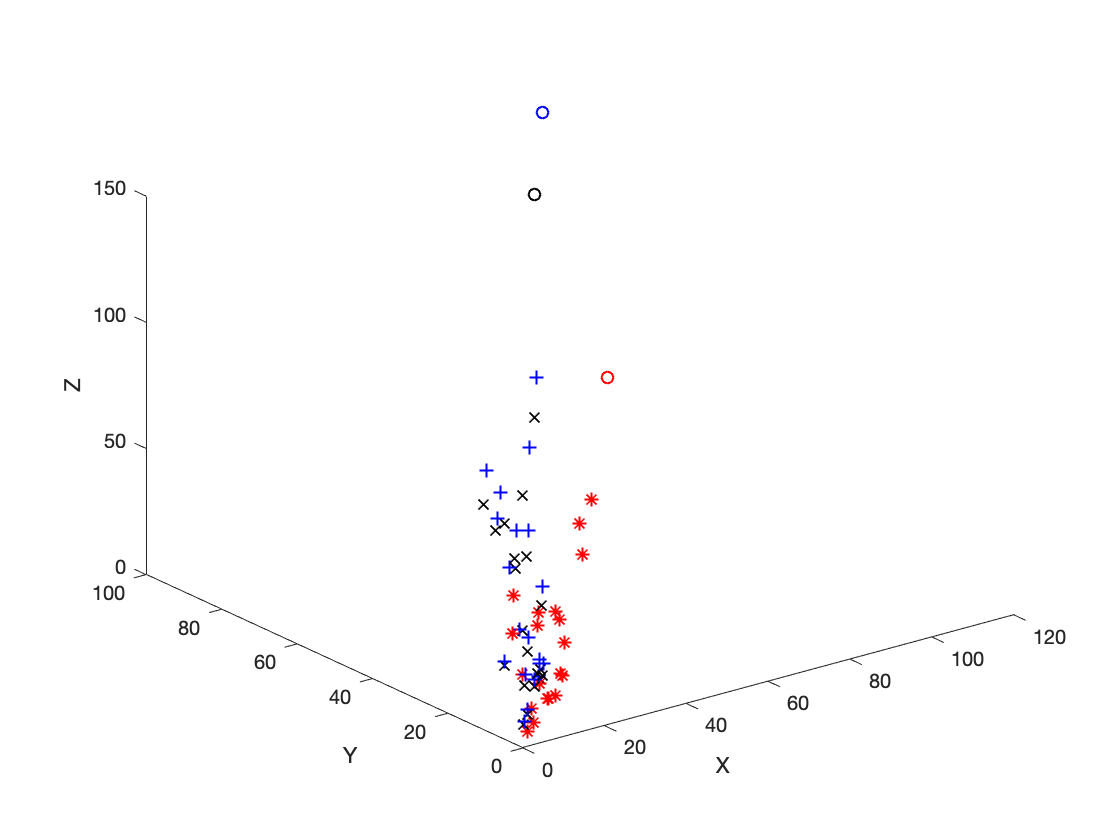

plot_XYZ

**5.6-5.7**

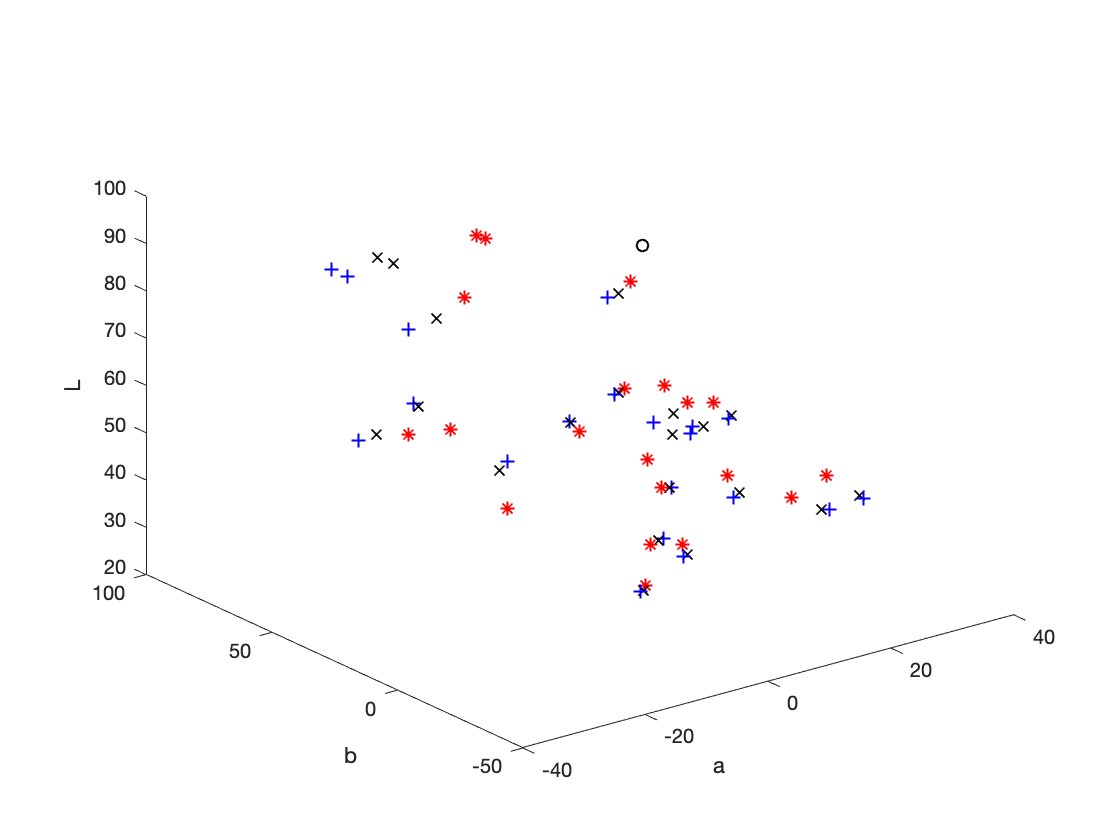

plot_Lab